% Variieren der Hyperparameter sigmaF, sigmaN, l und berechnen der logLikelihood
close
clear
clc
load dataOut/testData26.mat

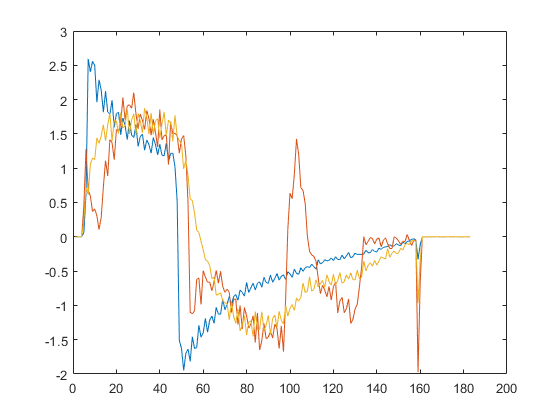


%xD = [testData.x1, testData.x2, testData.x3, testData.u];
xD = [testData.x1, testData.x2,testData.x3, testData.u1];
dxD = [testData.dx1, testData.dx2, testData.dx3];
%yD = [testData.y1, testData.y2, testData.y3];

D = size(xD,1);
n = size(xD,2);
m = size(dxD,2);

for i = 1 : n
    xStd(1,i) = std(xD(:,i));
    xMean(1,i) = mean(xD(:,i));

end
for i = 1 : m
    dxStd(1,i) = std(dxD(:,i));
    dxMean(1,i) = mean(dxD(:,i));
end

xDnorm = (xD - xMean)./ xStd;
dxDnorm = (dxD - dxMean)./ dxStd;

plot(dxDnorm)

gpml methods

%   meanfunc = [];                    % empty: don't use a mean function
%   covfunc = @covSEiso;              % Squared Exponental covariance function
%   likfunc = @likGauss;              % Gaussian likelihood
% hyp = struct('mean', [], 'cov', [0 0], 'lik', -1);
% hyp2 = minimize(hyp, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, xDnorm, dxDnorm(:,3));
% 
% hyperparameter.l = exp(hyp2.cov(1)); %length scale
% hyperparameter.sigmaF = exp(hyp2.cov(2)); %signal std Dev sigmaF
% hyperparameter.sigmaN = exp(hyp2.lik(1)); %noise std dev sigmaN
% hyperparameter

**Variation aller Hyperparameter gleichzeitig**

gpNo= 1;
yD = dxD(:,gpNo);
yMean = dxMean(1,gpNo);
yStd = dxStd(1,gpNo);

%1
sigmaF = (logspace(-2,1,20)).';
sigmaN = (logspace(-2,1,20)).';
l = (logspace(-2,1,20)).';

sigmaF = (5:0.05:6).';
%sigmaF = (0.9:-0.01:0.5);
%sigmaF = 0.86;
sigmaN = (0.045:0.0005:0.05).';
%sigmaN = 0.56;
l = (0.5:0.005:0.6).';
logLike = zeros(length(sigmaF),length(sigmaN),length(l));
for i = 1: length(sigmaF)
    for j = 1: length(sigmaN)
        for k = 1: length(l)
            hyperparameter.sigmaF = sigmaF(i);
            hyperparameter.l = l(k);
            hyperparameter.sigmaN = sigmaN(j);
            
            K=CovMatrix(xDnorm,hyperparameter,@squaredExponentialKernel);
            H = basisFkt(D, @meanDx1,xD, yMean, yStd);
            logLike(i,j,k) = logLikelihoodBasis(yD,K,hyperparameter,H);
            %logLike(i,j,k)=logLikelihood_V1(dxDnorm(:,1),K,sigmaN(j)); 
        end
    end
end

Finden des Maximums 

maxLik=max(logLike(~isinf(logLike)))
%[sigmaFmax sigmaNmax lMax ] = find(lL_FNl == maxLik)
[r,c,v] = ind2sub(size(logLike),find(logLike == maxLik))
sigmaFmax = sigmaF(r)
sigmaNmax = sigmaN(c)
lMax = l(v)

% save('hyperparameter','logLike','sigmaF','sigmaN','l','sigmaFmax','sigmaNmax','lMax')

Plotten der Höhenlinien

% l fixiert
[x,y] = meshgrid(sigmaF,sigmaN);
x =x.';
y = y.';
logLike_lmax = logLike(:,:,v);

figure(1)
%contour(x,y,logLike_lmax,'ShowText','on')
%ylim([0.1 0.5]);
%xlim([0 0.5]);
xlabel('sigmaF')
ylabel('sigmaN')

**Hyperparameter am Optimum festhalten und einen variieren**

% % sigma F varrieren

% sigmaF = (0.1:0.01:0.4).';
% sigmaN = 0.35;
% l = 0.34;
% logLike_sF = zeros(size(sigmaF));
% for i = 1: length(sigmaF)
%         K=CovMatrix([u,x],sigmaF(i),l);
%         logLike_sF(i)=logLikelihood_V1(dx,K,sigmaN);
% end
% figure(2)
% plot (sigmaF, logLike_sF)
% xlabel('sigmaF')
% ylabel('logLike')

% % sigma N varrieren

% sigmaF = 0.3;
% sigmaN = (0.3:0.01:0.5).';
% l = 0.4;
% logLike_sN = zeros(size(sigmaN));
% for i = 1: length(sigmaN)
%         K=CovMatrix([u,x],sigmaF,l);
%         logLike_sN(i)=logLikelihood_V1(dx,K,sigmaN(i));
% end
% figure(3)
% plot (sigmaN, logLike_sN)
% xlabel('sigmaN')
% ylabel('logLike')

% % l varrieren

% sigmaF = 0.1;
% sigmaN = 0.35;
% l =(0.1:0.1:5).';
% logLike_l = zeros(size(l));
% for i = 1: length(l)
%         K=CovMatrix([u,x],sigmaF,l(i));
%         logLike_l(i)=logLikelihood_V1(dx,K,sigmaN);
% end
% figure(4)
% plot (l, logLike_l)
% xlabel('l')
ylabel('logLike')

function logL = logLikelihoodBasis(y,K,hyperparameter,H)
    %Log Likelihood Version 1
    sigmaN = hyperparameter.sigmaN;
    n = length(y);
    Ky = K + sigmaN^2 * eye(n);
    KyInv = (Ky)^-1;
    A =  H  * KyInv * H.'; 
    C = KyInv * H.' * A^-1 * H * KyInv;
    logL = -1/2 * y.' * KyInv * y - 1/2 * log(det(Ky)) - 1/2*(n-2)* log(2*pi) + 1/2 * y.' * C * y - 1/2 * log(det(A));
end

function H = basisFkt(n, meanFct,xD, yMean, yStd)
    noParam.beta = 1;
    dimH = 2;
    H = zeros(dimH, n);
    for i = 1 : n
        H(:,i) = meanFct(xD(i,:),noParam).';
        for j = 1 : dimH
            H(j,i) = (H(j,i) - yMean) / yStd;
        end
    end
end